% Parameters
R = .25;                % Radius of the slinky coil
n_turns = 11.25;         % Number of turns
l = 3.5 

l = 3.5000

pitch = l/11;            % Distance between each turn
d = 0.0171

d = 0.0171

S_ =1.50

S_ = 1.5000

t = linspace(S_, n_turns * 2 * pi, 1000);  % Parameter t

% Original parametric equations for the slinky
x = pitch * t / (2 * pi);  % Moves along the x-axis
y = R * cos(t);            % Circular motion in the y-direction
z = R * sin(t);            % Circular motion in the z-direction

% Define the custom transformation matrix
theta_xy = pi - atan(d/pitch);  % Angle between X' and Y' (pi/10 radians)
theta_xz = pi/2;   % Angle between X' and Z' (90 degrees)
theta_yz = pi/2;   % Angle between Y' and Z' (90 degrees)

% Transformation matrix for custom coordinate system
T = [1, cos(theta_xy), 0;
     0, sin(theta_xy), cos(theta_yz);
     0, 0, sin(theta_xz)];

% Apply the transformation to each point
new_coords = T * [x; y; z]

new_coords =     0.0583    0.0791    0.0999    0.1206    0.1411    0.1614    0.1814    0.2009    0.2200    0.2385    0.2564    0.2736    0.2901    0.3057    0.3204    0.3342    0.3470    0.3588    0.3695    0.3791    0.3876    0.3949    0.4010    0.4060    0.4097    0.4123    0.4136    0.4138    0.4128    0.4107    0.4075    0.4031    0.3977    0.3914    0.3840    0.3758    0.3667    0.3568    0.3462    0.3349    0.3231    0.3107    0.2979    0.2848    0.2713    0.2577    0.2439    0.2302    0.2164    0.2028
    0.0009    0.0000   -0.0009   -0.0018   -0.0027   -0.0036   -0.0045   -0.0054   -0.0062   -0.0070   -0.0078   -0.0086   -0.0092   -0.0099   -0.0105   -0.0111   -0.0116   -0.0120   -0.0124   -0.0127   -0.0130   -0.0132   -0.0133   -0.0134   -0.0134   -0.0134   -0.0132   -0.0131   -0.0128   -0.0125   -0.0122   -0.0117   -0.0113   -0.0107   -0.0101   -0.0095   -0.0088   -0.0081   -0.0074   -0.0066   -0.0057   -0.0049   -0.0040   -0.0031   -0.0022   -0.0013   -0.0004    0.0006    0.

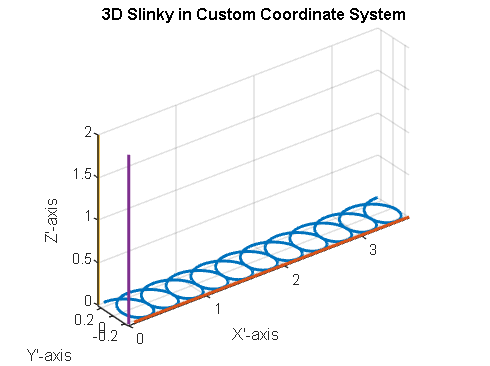


% Extract the new coordinates
x_new = new_coords(1, :);
z_new = new_coords(2, :);
y_new = new_coords(3, :);

x_line = linspace(min(x_new), max(x_new), 1000);
z_line = zeros(1000, 1);
y_line = min(y_new).*ones(1000, 1) - d*.55;

x_dept = ones(200, 1) *-.01;
z_dept = linspace(0,2, 200);

y_dept_in = ones(200, 1) *0.25;;
y_dept_out = ones(200, 1) * -0.25 - d*.55;;


% Plot the slinky in the new coordinate system
figure;
plot3(x_new, y_new, z_new, 'LineWidth', 2)
hold on
plot3(x_line, y_line, z_line, 'LineWidth', 2);
grid on;
plot3(x_dept, y_dept_in, z_dept, 'LineWidth', 2)
hold on
plot3(x_dept, y_dept_out, z_dept, 'LineWidth', 2)
hold on
xlabel('X''-axis');
ylabel('Y''-axis');
zlabel('Z''-axis');
title(['3D Slinky in Custom Coordinate System']);
axis equal;
view(3); 

% Parameters
R = .25;                % Radius of the slinky coil
n_turns = 11;         % Number of turns
l = 3.5 

l = 3.5000

pitch = l/11;            % Distance between each turn
d = 0.0171

d = 0.0171

s_ = pi/2

s_ = 1.5708

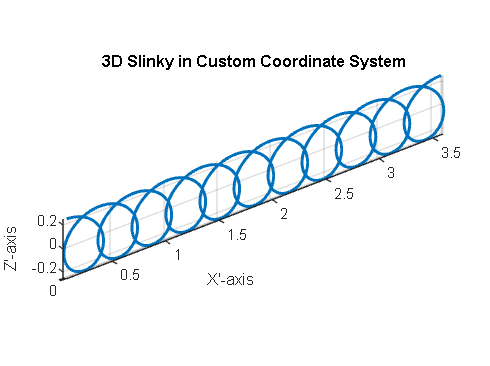

t = linspace(s_, n_turns * 2 * pi+ s_, 1000);  % Parameter t

% Original parametric equations for the slinky
x = pitch * t / (2 * pi);  % Moves along the x-axis
y = R * cos(t);            % Circular motion in the y-direction
z = R * sin(t);            % Circular motion in the z-direction

% Define the custom transformation matrix
theta_xy = pi - atan(d/pitch);  % Angle between X' and Y' (pi/10 radians)
theta_xz = pi/2;   % Angle between X' and Z' (90 degrees)
theta_yz = pi/2;   % Angle between Y' and Z' (90 degrees)

% Transformation matrix for custom coordinate system
T = [1, cos(theta_xy), 0;
     0, sin(theta_xy), cos(theta_yz);
     0, 0, sin(theta_xz)];

% Apply the transformation to each point
new_coords = T * [x; y; z];

% Extract the new coordinates
x_new = new_coords(1, :);
y_new = new_coords(2, :);
z_new = new_coords(3, :);

% Plot the slinky in the new coordinate system
figure;
plot3(x_new, y_new, z_new, 'LineWidth', 2);
grid on;
xlabel('X''-axis');
ylabel('Y''-axis');
zlabel('Z''-axis');
title(['3D Slinky in Custom Coordinate System']);
axis equal;
view(3);  % Set the view to 3D

% Parameters
R = .25;                % Radius of the slinky coil
n_turns = 11.25;         % Number of turns
l = 3.5 
pitch = l/11;            % Distance between each turn
d = 0.0171
S_ =1.50
t = linspace(S_, n_turns * 2 * pi, 1000);  % Parameter t

% Original parametric equations for the slinky
x = pitch * t / (2 * pi);  % Moves along the x-axis
y = R * cos(t);            % Circular motion in the y-direction
z = R * sin(t);            % Circular motion in the z-direction

% Define the custom transformation matrix
theta_xy = pi - atan(d/pitch);  % Angle between X' and Y' (pi/10 radians)
theta_xz = pi/2;   % Angle between X' and Z' (90 degrees)
theta_yz = pi/2;   % Angle between Y' and Z' (90 degrees)

% Transformation matrix for custom coordinate system
T = [1, cos(theta_xy), 0;
     0, sin(theta_xy), cos(theta_yz);
     0, 0, sin(theta_xz)];

% Apply the transformation to each point
new_coords = T * [x; y; z]

% Extract the new coordinates
x_new = new_coords(1, :);
y_new = new_coords(2, :);
z_new = new_coords(3, :);

x_line = linspace(min(x_new), max(x_new), 1000);
y_line = zeros(1000, 1);
z_line = min(z_new).*ones(1000, 1) - d*.55;

x_dept = ones(200, 1) *-.01;
y_dept = linspace(0,2, 200);

z_dept_in = ones(200, 1) *max(z_new);;
z_dept_out = ones(200, 1) *min(z_new) - d*.55;;


% Plot the slinky in the new coordinate system
figure;
plot3(x_new, y_new, z_new, 'LineWidth', 2)
hold on
plot3(x_line, y_line, z_line, 'LineWidth', 2);
grid on;
plot3(x_dept, y_dept, z_dept_in, 'LineWidth', 2)
hold on
plot3(x_dept, y_dept, z_dept_out, 'LineWidth', 2)
hold on
xlabel('X''-axis');
ylabel('Y''-axis');
zlabel('Z''-axis');
title(['3D Slinky in Custom Coordinate System']);
axis equal;
view(3);  % Set the view to 3D
% in this code make an adjustment so that slinky start before first maxima
% in Z axis and end before last minima of z axis and i also want to set the
% length and a value of revolution matlab may need to calculate correct  
% revolution value  to fill previous criteriea also calculate pitch value

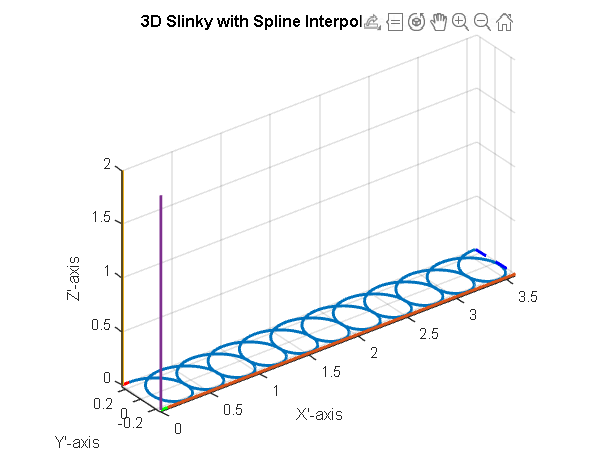

% Parameters
R = 0.25;                % Radius of the slinky coil
n_turns = 11.25;         % Number of turns
l = 3.5;
pitch = l / 11;          % Distance between each turn
d = 0.0171;
S_ = 1.50;
t = linspace(S_, n_turns * 2 * pi, 1000);  % Parameter t

% Original parametric equations for the slinky
x = pitch * t / (2 * pi);  % Moves along the x-axis
y = R * cos(t);            % Circular motion in the y-direction
z = R * sin(t);            % Circular motion in the z-direction

% Define the custom transformation matrix
theta_xy = pi - atan(d/pitch);  % Angle between X' and Y'
theta_xz = pi/2;   % Angle between X' and Z'
theta_yz = pi/2;   % Angle between Y' and Z'

% Transformation matrix for custom coordinate system
T = [1, cos(theta_xy), 0;
     0, sin(theta_xy), cos(theta_yz);
     0, 0, sin(theta_xz)];

% Apply the transformation to each point
new_coords = T * [x; y; z];

% Extract the new coordinates
x_new = new_coords(1, :);
z_new = new_coords(2, :);
y_new = new_coords(3, :);

% Line data
x_line = linspace(min(x_new), max(x_new), 1000);
z_line = zeros(1000, 1);
y_line = min(y_new) * ones(1000, 1) - d * 0.55;

x_dept = ones(200, 1) * -0.01;
z_dept = linspace(0, 2, 200);

y_dept_in = ones(200, 1) * 0.25;
y_dept_out = ones(200, 1) * -0.25 - d * 0.55;

% Spline interpolation data
spline_points = 100;

% Connect x_dept start to slinky start
x_spline1 = linspace(x_dept(1), x_new(1), spline_points);
y_spline1 = spline([x_dept(1), x_new(1)], [y_dept_in(1), y_new(1)], x_spline1);
z_spline1 = spline([x_dept(1), x_new(1)], [z_dept(1), z_new(1)], x_spline1);

% Connect x_dept_out to line start
x_spline2 = linspace(x_dept(1), x_line(1), spline_points);
y_spline2 = spline([x_dept(1), x_line(1)], [y_dept_out(1), y_line(1)], x_spline2);
z_spline2 = spline([x_dept(1), x_line(1)], [z_dept(1), z_line(1)], x_spline2);

% Connect slinky end to line end
x_spline3 = linspace(x_new(end), x_line(end), spline_points);
y_spline3 = spline([x_new(end), x_line(end)], [y_new(end), y_line(end)], x_spline3);
z_spline3 = spline([x_new(end), x_line(end)], [z_new(end), z_line(end)], x_spline3);

% Plot the slinky in the new coordinate system
figure;
plot3(x_new, y_new, z_new, 'LineWidth', 2)
hold on
plot3(x_line, y_line, z_line, 'LineWidth', 2);
grid on;
plot3(x_dept, y_dept_in, z_dept, 'LineWidth', 2)
hold on
plot3(x_dept, y_dept_out, z_dept, 'LineWidth', 2)
hold on

% Plot the spline interpolated lines
plot3(x_spline1, y_spline1, z_spline1, '--r', 'LineWidth', 2);  % x_dept start to slinky start
plot3(x_spline2, y_spline2, z_spline2, '--g', 'LineWidth', 2);  % x_dept_out to line start
plot3(x_spline3, y_spline3, z_spline3, '--b', 'LineWidth', 2);  % slinky end to line end

xlabel('X''-axis');
ylabel('Y''-axis');
zlabel('Z''-axis');
title('3D Slinky with Spline Interpolated Connections');
axis equal;
view(3);

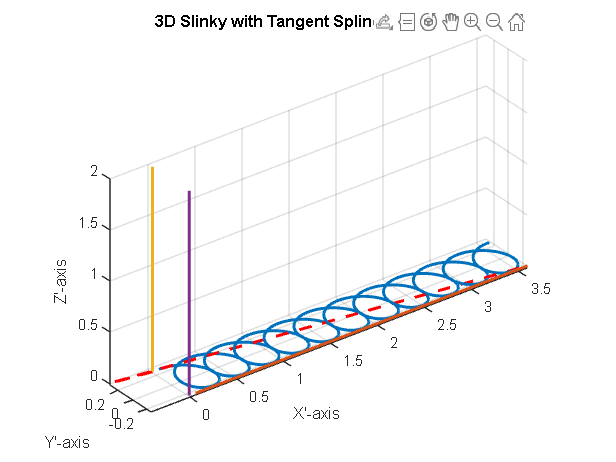

% Parameters
R = 0.25;                % Radius of the slinky coil
n_turns = 11.25;         % Number of turns
l = 3.5;
pitch = l / 11;          % Distance between each turn
d = 0.0171;
S_ = 1.50;
t = linspace(S_, n_turns * 2 * pi, 1000);  % Parameter t

% Original parametric equations for the slinky
x = pitch * t / (2 * pi);  % Moves along the x-axis
y = R * cos(t);            % Circular motion in the y-direction
z = R * sin(t);            % Circular motion in the z-direction

% Define the custom transformation matrix
theta_xy = pi - atan(d/pitch);  % Angle between X' and Y'
theta_xz = pi/2;   % Angle between X' and Z'
theta_yz = pi/2;   % Angle between Y' and Z'

% Transformation matrix for custom coordinate system
T = [1, cos(theta_xy), 0;
     0, sin(theta_xy), cos(theta_yz);
     0, 0, sin(theta_xz)];

% Apply the transformation to each point
new_coords = T * [x; y; z];

% Extract the new coordinates
x_new = new_coords(1, :);
z_new = new_coords(2, :);
y_new = new_coords(3, :);

% Line data
x_line = linspace(min(x_new), max(x_new), 1000);
z_line = zeros(1000, 1);
y_line = min(y_new) * ones(1000, 1) - d * 0.55;

x_dept = ones(200, 1) * -0.01;
z_dept = linspace(0, 2, 200);

y_dept_in = ones(200, 1) * 0.25;
y_dept_out = ones(200, 1) * -0.25 - d * 0.55;

% Tangent vector estimation at connection points
tangent_slinky_start = [diff(x_new(1:2)); diff(y_new(1:2)); diff(z_new(1:2))];
tangent_line_end = [diff(x_line(end-1:end)); diff(y_line(end-1:end)); diff(z_line(end-1:end))];

% Combine start and end points for interpolation
control_pts = [x_dept(1), x_new(1), x_line(end);
               y_dept_in(1), y_new(1), y_line(end);
               z_dept(1), z_new(1), z_line(end)];

% Perform spline interpolation on the control points
t_spline = linspace(0, 1, 100);
spline_curve = spline([0, 0.5, 1], control_pts, t_spline);

% Plot the slinky in the new coordinate system
figure;
plot3(x_new, y_new, z_new, 'LineWidth', 2);
hold on;
plot3(x_line, y_line, z_line, 'LineWidth', 2);
grid on;
plot3(x_dept, y_dept_in, z_dept, 'LineWidth', 2);
plot3(x_dept, y_dept_out, z_dept, 'LineWidth', 2);

% Plot the spline connection
plot3(spline_curve(1, :), spline_curve(2, :), spline_curve(3, :), '--r', 'LineWidth', 2);

xlabel('X''-axis');
ylabel('Y''-axis');
zlabel('Z''-axis');
title('3D Slinky with Tangent Spline Connections');
axis equal;
view(3);

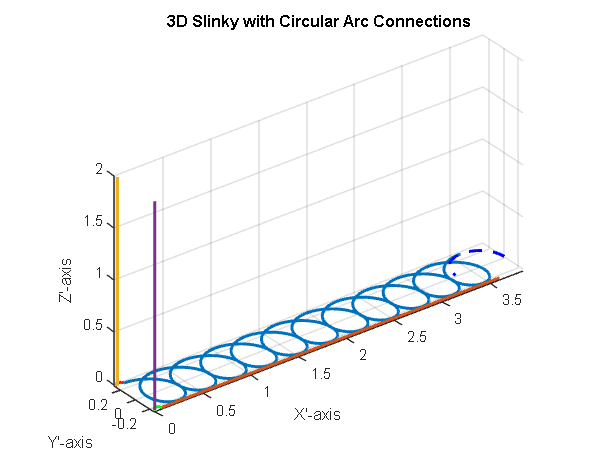

% Parameters
R = 0.25;                % Radius of the slinky coil
n_turns = 11.25;         % Number of turns
l = 3.5;
pitch = l / 11;          % Distance between each turn
d = 0.0171;
S_ = 1.50;
t = linspace(S_, n_turns * 2 * pi, 1000);  % Parameter t

% Original parametric equations for the slinky
x = pitch * t / (2 * pi);  % Moves along the x-axis
y = R * cos(t);            % Circular motion in the y-direction
z = R * sin(t);            % Circular motion in the z-direction

% Define the custom transformation matrix
theta_xy = pi - atan(d/pitch);  % Angle between X' and Y'
theta_xz = pi/2;   % Angle between X' and Z'
theta_yz = pi/2;   % Angle between Y' and Z'

% Transformation matrix for custom coordinate system
T = [1, cos(theta_xy), 0;
     0, sin(theta_xy), cos(theta_yz);
     0, 0, sin(theta_xz)];

% Apply the transformation to each point
new_coords = T * [x; y; z];

% Extract the new coordinates
x_new = new_coords(1, :);
z_new = new_coords(2, :);
y_new = new_coords(3, :);

% Line data
x_line = linspace(min(x_new), max(x_new), 1000);
z_line = zeros(1000, 1);
y_line = min(y_new) * ones(1000, 1) - d * 0.55;

x_dept = ones(200, 1) * -0.01;
z_dept = linspace(0, 2, 200);

y_dept_in = ones(200, 1) * 0.25;
y_dept_out = ones(200, 1) * -0.25 - d * 0.55;

% Tangent calculation for circular arc connections
tangent_slinky_start = [x_new(2) - x_new(1); y_new(2) - y_new(1); z_new(2) - z_new(1)];
tangent_slinky_end = [x_new(end) - x_new(end-1); y_new(end) - y_new(end-1); z_new(end) - z_new(end-1)];
tangent_line_start = [x_line(2) - x_line(1); y_line(2) - y_line(1); z_line(2) - z_line(1)];
tangent_line_end = [x_line(end) - x_line(end-1); y_line(end) - y_line(end-1); z_line(end) - z_line(end-1)];

% Connecting arc using circular blending
arc_points = 50;

% Arc from x_dept to slinky start
arc1 = circular_arc(x_dept(1), y_dept_in(1), z_dept(1), x_new(1), y_new(1), z_new(1), tangent_slinky_start, arc_points);

% Arc from x_dept_out to line start
arc2 = circular_arc(x_dept(1), y_dept_out(1), z_dept(1), x_line(1), y_line(1), z_line(1), tangent_line_start, arc_points);

% Arc from slinky end to line end
arc3 = circular_arc(x_new(end), y_new(end), z_new(end), x_line(end), y_line(end), z_line(end), tangent_slinky_end, arc_points);

% Plot the slinky in the new coordinate system
figure;
plot3(x_new, y_new, z_new, 'LineWidth', 2);
hold on;
plot3(x_line, y_line, z_line, 'LineWidth', 2);
grid on;
plot3(x_dept, y_dept_in, z_dept, 'LineWidth', 2);
plot3(x_dept, y_dept_out, z_dept, 'LineWidth', 2);

% Plot the circular arcs
plot3(arc1(1,:), arc1(2,:), arc1(3,:), '--r', 'LineWidth', 2);
plot3(arc2(1,:), arc2(2,:), arc2(3,:), '--g', 'LineWidth', 2);
plot3(arc3(1,:), arc3(2,:), arc3(3,:), '--b', 'LineWidth', 2);

xlabel('X''-axis');
ylabel('Y''-axis');
zlabel('Z''-axis');
title('3D Slinky with Circular Arc Connections');
axis equal;
view(3);


% Circular Arc Function

function arc = circular_arc(x1, y1, z1, x2, y2, z2, tangent_vec, n_points)
    midpoint = [(x1 + x2)/2, (y1 + y2)/2, (z1 + z2)/2];
    arc_radius = norm([x1 - midpoint(1), y1 - midpoint(2), z1 - midpoint(3)]);
    theta = linspace(0, pi, n_points);
    arc_x = midpoint(1) + arc_radius * cos(theta);
    arc_y = midpoint(2) + arc_radius * sin(theta);
    arc_z = linspace(z1, z2, n_points); % Approximate z motion
    arc = [arc_x; arc_y; arc_z];
end
